# ECE 486 S23 Project Section 2

### @author Laurent Zheng (20818351)

## 1. Task Space

The task is to intercept the ball's trajectory within the defined cuboid. In this case, the task space of the ball is the 3-dimensional Euclidean space, or $\[\mathbb{E}^3\]$, that describes the locations in which the ball can be contacted by the paddle. Since the orientation of the ball is not considered, there are only 3 degrees of freedom needed to express the task space of the ball. 

## 2. Work Space

The work space is the reachable configuration for the paddle to be in contact with the ball. This can be described by the 3-dimensional Euclidean space, and an angle about the z-axis that describes the orientation of the paddle at the point of contact. This can be written as $\mathbb{E}^3 \times S^1$, which gives 4 degrees of freedom for the work space. 

If we fix the orientation of the paddle at some known $\theta$, the task space is equivalent to the work space, and can be visualized as the cuboid draw below:

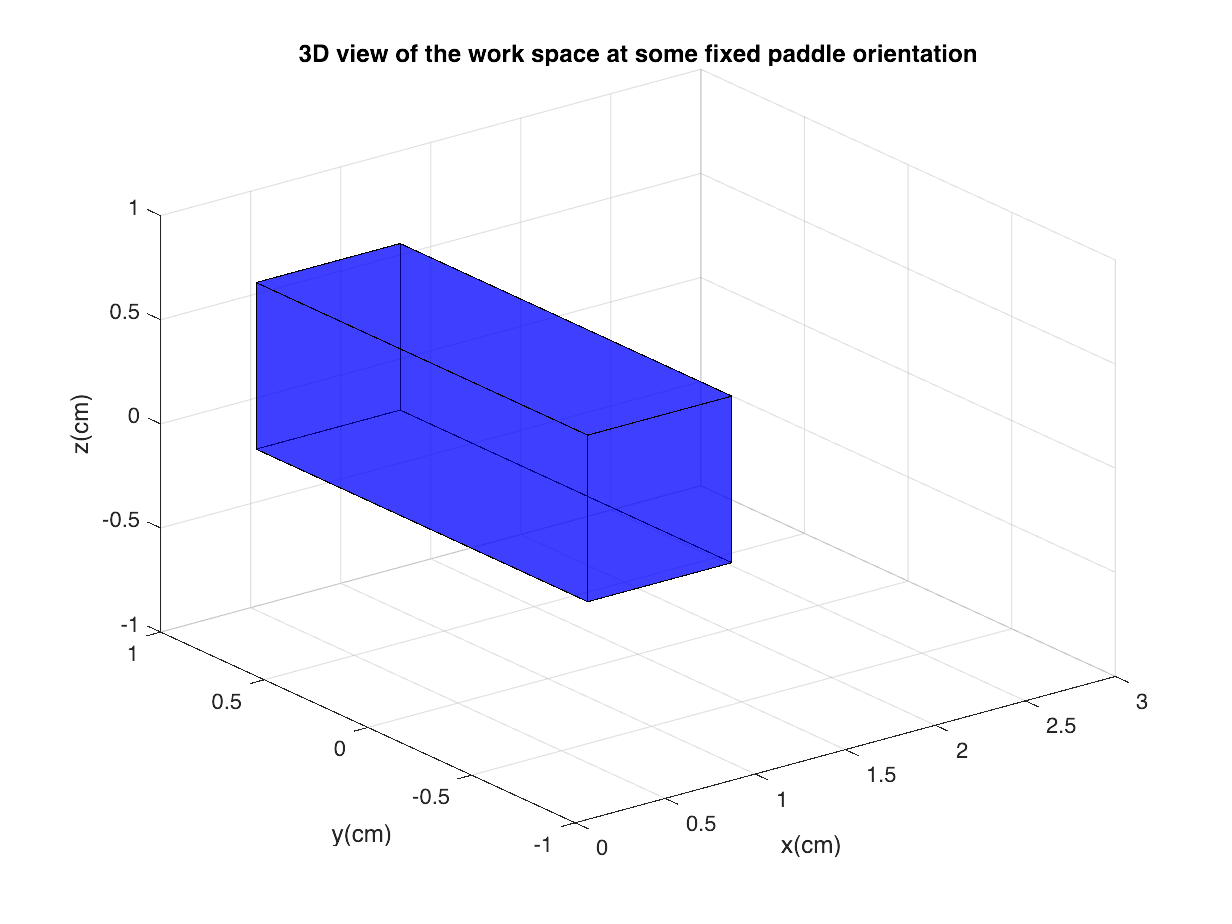

xMin = 0.3;
xMax = 1.1;
yMin = -0.8;
yMax = 0.8;
zMin = -0.1;
zMax = 0.7;

% vertices of prism
vertices = [
    xMin, yMin, zMin;
    xMin, yMin, zMax;
    xMin, yMax, zMin;
    xMin, yMax, zMax;
    xMax, yMin, zMin;
    xMax, yMin, zMax;
    xMax, yMax, zMin;
    xMax, yMax, zMax
];

% planes
faces = [
    1, 2, 4, 3;
    5, 6, 8, 7;
    1, 2, 6, 5;
    3, 4, 8, 7;
    1, 3, 7, 5;
    2, 4, 8, 6
];

% plot
figure;
for i = 1:size(faces, 1)
    fill3(vertices(faces(i, :), 1), vertices(faces(i, :), 2), vertices(faces(i, :), 3), 'blue', 'FaceAlpha', 0.5);
    hold on;
end

grid on;
xlabel('x(cm)');
ylabel('y(cm)');
zlabel('z(cm)');
xlim([0, 3]);
ylim([-1, 1]);
zlim([-1, 1]);
title('3D view of the work space at some fixed paddle orientation');
hold off;

Note that this cuboid only illustrates the volume where the centre point of the front side of the paddle could reach. Taking into account the dimensions of the paddle, the size of the workspace would have to increase by 15*cos(15°) = 14.48cm in its y component and 15cm in its z component. This is because the maximum space where the ball would be intercepted at some determined orientation of the paddle includes the entire surface area of the paddle. We cannot say that the x component also increased 15*sin(15°) = 3.88cm since the requirement at the lower bound of $\theta = 0$ at the front or back surface would not be acheived. We can however, restrict our workspace to be the region where the ball is intercepted at the middle of the paddle for a known angle, which would be exactly the volumn as illustrated above.

## 3. Generate Ball Trajectory

The ball's trajectory is generated by updating the velocity and position of the ball at each time stamp. For each iteration of updates, the previous values are used to get the next set of values.  Where $p_{next} = p_{prev} + v_{prev}t_s + \frac{1}{2}gt_s^2$


$$v_{next} = v_{prev} + gt_s$$



$$t_{next} = t_{prev} + t_s$$


This continues until we reach a position where the z component is below -0.1. Furthermore, for each iteration, the upcoming position is checked to be within cuboid, and correspondingly updates the "in_range" vector. The last part of each output where the ball leaves the cuboid (and not come back) will be truncated.

Example of generating a ball trajectory with initial conditions $v_0 = [-7, 0, 2] ^T$ and $t_s = 10$ms:

v0 = [-7; 0; 2];
ts = 0.01;
[p_ball, t_ball, in_range] = ball_trajectory(v0, ts);

Outputs:

display(p_ball);

p_ball =     3.0000    2.9300    2.8600    2.7900    2.7200    2.6500    2.5800    2.5100    2.4400    2.3700    2.3000    2.2300    2.1600    2.0900    2.0200    1.9500    1.8800    1.8100    1.7400    1.6700    1.6000    1.5300    1.4600    1.3900    1.3200    1.2500    1.1800    1.1100    1.0400    0.9700    0.9000    0.8300    0.7600    0.6900    0.6200    0.5500    0.4800    0.4100    0.3400    0.2700
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0195    0.0380    0.0556    0.0722    0.0877    0.1023    0.1160    0.1286    0.1403    0.1509    0.1606    0.1694    0.1771    0.1839    0.1896    0.1944    0.1982    0.201

display(t_ball);

t_ball =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900


display(in_range);

in_range =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0


## 3. Moving into Contact

To express the position of the ball in the frame of the home pose, we can apply a homogeneous transformation of the position in the fixed frame {s}. The home pose can be expressed in the frame {s} with the homogeneous matrix


$$T_{sh} =   \pmatrix{R_{sh} & p_{sh} \cr 0 & 1}$$


This gives us the position of the ball in the home frame to be expressed as


$$p_{hb} = T_{hs}p_{sb} = T_{sh}^{-1}p_{sb}$$


To move the end effector from the home frame to be in contact with the ball, we can break the homogeneous transformation to its rotation and translation components. With respect to the home frame, we rotate the paddle with respects to its y-axis for angle $\theta$. Furthermore, the translation would need to move the paddle to the surface of the ball, 1cm away from the centre of the ball. The vector for this translation component can be expressed as

$p_{hc} = p_{hb} - R_y(\theta)\pmatrix{0 \cr 0 \cr 0.01}$, 

where the second component is the position of the ball with respect to the paddle at the final pose.

Finally, this gives us the homogeneous transformation


$$T_{hc} =   \pmatrix{R_y(\theta) & p_{hc} \cr 0 & 1}$$
 

corresponding the transformation from the home pose to the final pose in the home home, and


$$T_{sc} = T_{sh} T_{hc}$$


to be the same transformation expressed in the fixed frame.

Example of getting the transformation to contact the ball with $\theta = \pi/12$ and the position of the ball in the fixed frame $p_{sb} = [0.3, 0.1, 0.7]^T$


theta = pi/12; % 15 degrees
p_sb = [0.3; 0.1; 0.7];
[p_hb, T_sc, T_hc] = make_contact(p_sb, theta); 

Outputs:

display(p_hb);

p_hb =     0.1000
    0.4500
    0.0500


display(T_sc);

T_sc =    -0.2588         0    0.9659    0.2903
    0.9659         0    0.2588    0.0974
         0    1.0000         0    0.7000
         0         0         0    1.0000


display(T_hc);

T_hc =     0.9659         0    0.2588    0.0974
         0    1.0000         0    0.4500
   -0.2588         0    0.9659    0.0403
         0         0         0    1.0000


## Appendix: Function Definitions

The following function outlines the procedure of generation trajectory as mentioned in the above sections. This function would be used later in the project to generate the trajectory of the robot's end effector where the final position of the paddle intercept the trajectory of the ball. We can use the t_ball vector to calculate the optimal configuration to meet the ball in this trajectory given the delay of the arm moving into the target pose. Lastly, we can see if the ball would ever be in range for the paddle to intercept it by examning the in_range vector. When in_range is an all zero vector, we can denote that the task would be unachievable.

function [p_ball, t_ball, in_range] = ball_trajectory(v0, ts)
% Inputs:
% v0 = [vx; vy; vz] - initial velocity measured in fixed frame
% ts - the sampling rate (time step) in seconds


% Constants
g = [0;0;-9.81];
p0 = [3;0;0];
t0 = 0;

% Generate the position array p_ball, 
% the time vector t_ball,
% and the logical vector in_range.

% The first element of the outputs are the defined initial conditions
p_ball = p0;
t_ball = t0;
v_ball = v0;
in_range = 0;

% Append a new set of values for p,v,t,and in_range 
% until the ball is 0.1m below the z axis
while p_ball(end) > -0.1

    % the next position, velocity and timestamps 
    % are calculated from the previous.
    p_next = p_ball(:,end) + v_ball(:,end) * ts + (g*ts*ts)/2;
    v_next = v_ball(:,end) + g*ts;
    t_next = t_ball(end) + ts;

    % boolean for the position 
    % x in [0.3, 1.1]
    % y in [-0.8, 0.8]
    % z in [-0.1, 0.7]
    in_range_next = p_next(1) >= 0.3 && p_next(1) <= 1.1 && ...
                    p_next(2) >= -0.8 && p_next(2) <= 0.8 && ...
                    p_next(3) >= -0.1 && p_next(3) <= 0.7;
    
    % append new values in each of the arrays
    p_ball = [p_ball, p_next];
    v_ball = [v_ball, v_next];
    t_ball = [t_ball, t_next];
    in_range = [in_range, in_range_next];

end

% Look at the last time that the ball was in the cuboid
in_range_indices = find(in_range > 0);

% Truncate all the index after the last time it exists the cuboid
% Do nothing if it never enters the cuboid
if ~isempty(in_range_indices)
    last_index = max(in_range_indices) + 1;
    p_ball = p_ball(:, 1:last_index);
    t_ball = t_ball(:, 1:last_index);
    in_range = in_range(:, 1:last_index);
end


end

The following function outlines the procedure of obtaining the homogeneous transformation from the home pose to the contact pose in the home frame and the fixed frame, as wells the position of the ball in the home frame given the position of the ball in the fix frame. This function would be used later in the project to generate the trajectory of the robot's end effector where the final position of the paddle intercept the trajectory of the ball. We can use the transformation at either frame to then get the motion required at each joint of the robot to get to such pose.

function [p_hb, T_sc, T_hc] = make_contact(p_sb, theta)
% Inputs:
% p_sb - fixed ball position (relative to the fixed frame)
% theta - desired paddle contact angle about a vertical axis

% Express home axis in the fix frame
R_sh = [0 0 1; 1 0 0; 0 1 0];
p_sh = [0.25; 0; 0.25];
T_sh = [R_sh, p_sh; 0, 0, 0, 1];

% Get ball position in home frame:
% equivalent to inverse(T_hs) * p_sb
p_hb = T_sh \ [p_sb; 1];
p_hb = p_hb(1:end-1);

% Generate rotation matrix about y-axis in the home frame to tilt the
% paddle, and get the translation based on the position of the ball.
R_hc = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
p_hc = p_hb - (R_hc * [0; 0; 0.01]);
T_hc = [R_hc, p_hc; 0, 0, 0, 1];

% Subscript cancelation to get the same transformation in the fixed frame
T_sc = T_sh * T_hc;

end